clc; clear; close all;

% 定义区间
x = linspace(-2,2,1000);

% 定义分段函数
f = zeros(size(x));                 % 先初始化为0
f(x < -0.5) = -1;       % 区间 [-1.5, -0.5)
f(x >= -0.5 & x < 0.5) = 0;         % 区间 [-0.5, 0.5)
f(x >= 0.5) = 1;         % 区间 [0.5, 1.5]

% 绘图
figure;
plot(x, f, 'LineWidth',2, 'DisplayName', 'reference');
ylim([-1.5, 1.5]); xlim([-2, 2]);
xlabel('x'); ylabel('f(x)');
grid on;
hold on

xx = linspace(-0.5, 0.5, 200)

xx =    -0.5000   -0.4950   -0.4899   -0.4849   -0.4799   -0.4749   -0.4698   -0.4648   -0.4598   -0.4548   -0.4497   -0.4447   -0.4397   -0.4347   -0.4296   -0.4246   -0.4196   -0.4146   -0.4095   -0.4045   -0.3995   -0.3945   -0.3894   -0.3844   -0.3794   -0.3744   -0.3693   -0.3643   -0.3593   -0.3543   -0.3492   -0.3442   -0.3392   -0.3342   -0.3291   -0.3241   -0.3191   -0.3141   -0.3090   -0.3040   -0.2990   -0.2940   -0.2889   -0.2839   -0.2789   -0.2739   -0.2688   -0.2638   -0.2588   -0.2538


yy = zeros(1, 200);
for i = 1:length(xx)
    x = xx(i);
    yy(i) = recon_THINC(-1, 0, 1, -0.5, x, 0.5, 1.5);
end
plot(xx, yy, 'LineWidth',2,'DisplayName', 'thinc')

xa = -0.5;
xb = 0.5;
uavem = -1;
uave = 0;
uavep = 1;
lambda = 1;
plot(xx, myInterp1(xx,  xa, xb, uavem, uave, 1), 'LineWidth',2,'DisplayName', 'exp1')
wenoExp3(uavem, uave, uavep, 1, 1)

ans = 0.4998

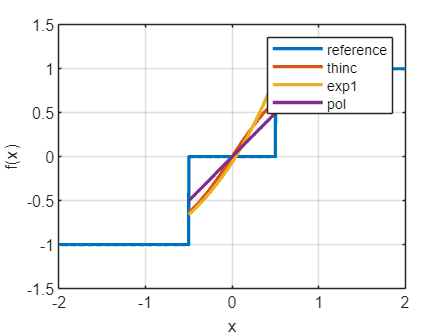

% plot(xx, myInterp2(xx,  xa, xb, uavem, uave, 3),  'DisplayName', 'exp2')
% plot(xx, myInterp3(xx,  xa, xb, uavem, uave, 5),  'DisplayName', 'exp3')
% plot(xx, myInterp4(xx,  xa, xb, uavem, uave, 1),  'DisplayName', 'exp4')
plot(xx, myInterp0(xx,  xa, xb, uavem, uave), '-' , 'LineWidth',2,'DisplayName','pol')
legend

function val = recon_THINC(uavem, uave, uavep, xa, xp, xb, beta)
    % 输入：
    %   uavem: 左邻单元平均值
    %   uave : 当前单元平均值
    %   uavep: 右邻单元平均值
    %   gp   : 高斯点编号 (1-based index)


    % 中心值与上下界
    Uc   = uave;
    Qmin = min(uavem, uavep);
    Qmax = max(uavem, uavep) - Qmin;

    theta = sign(uavep - uavem);

    % 计算参数
    C   = (Uc - Qmin + 1e-20) / (Qmax + 1e-20);
    B   = exp(theta * beta * (2.0 * C - 1.0));
    A   = (B / cosh(beta) - 1.0) / tanh(beta); %#ok<NASGU> % 保留和C++一致
    xc  = (exp(beta) - B) / (B - exp(-beta));
    xcc = log(xc) / (2.0 * beta);


    val = 0.5 * Qmax * (1 + theta * tanh(beta * ((xp-xa)/(xb-xa) - xcc))) + Qmin;

end